# Tank Blending Simulation

Create a dynamic model of concentration and temperature based on a physics-based derivation from species and energy balance equations. A mixing tank has a liquid inlet stream and outlet stream. The tank is well mixed so the concentration and temperature are assumed to be the same throughout the reactor.

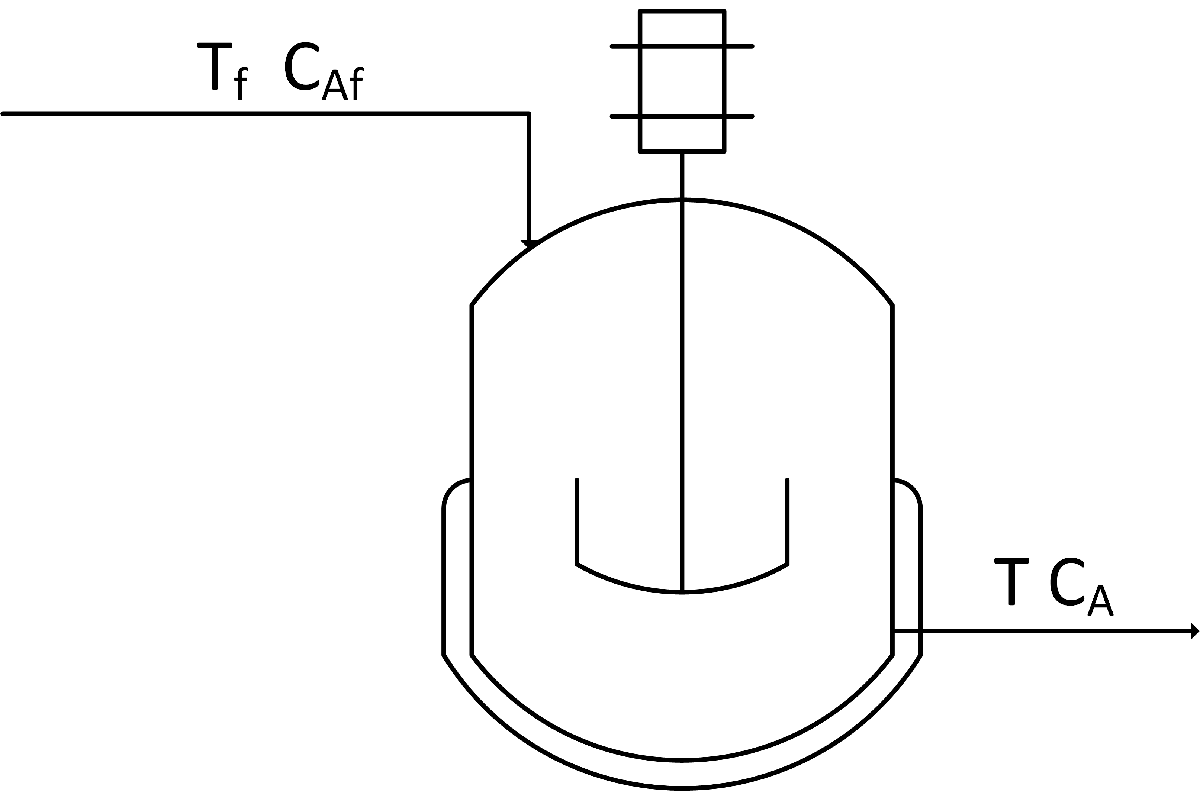

Start with the species and energy balance equations and derive the dynamic concentration and temperature response. Develop the concentration response and then add the temperature response. Assume a constant volume $V$ of $100 \text{m}^3
$ and an inlet flow rate $\dot{V}$ or $q$ of$100 \frac{\text{m}^3}{\text{hr}$.

clc; clear all; close all;
V = 100;  % Volume (m^3)
q = 100;  % Volumentric flowrate (m^3/hr)

### Species Balance

viewSolutionSpecies(false)

The first objective is to predict the concentration of *A* over a simulation time horizon. A species balance is created by relating the accumulation, inlet, and outlet terms of the number of moles *n* of species $A
$. The accumulation of $A$, $\frac{d(nA)}{dt}$, in a control volume is calculated by inlet, outlet, reaction generation, and reaction consumption rate. Without looking further, try to derive the material balance in the cells below. Then, check your work.

Initial Conditions

% Initial Concentration
Ca0 = 0.0;
% Feed Temperature (K)
Tf = 300;
% Feed concentration (mol/m^3)
Caf = 1;

Time interval

time = linspace(0, 10, 101);

CREATE A FUNCTION TO MODEL CHANGE IN CONCENTRATION OF A OVER TIME. THEN, USE` ode45 `TO SIMULATE THE CHANGE IN CONCENTRATION. FINALLY, PLOT THE RESULTS


$$\frac{d n_{A}}{d t}=\sum n_{A_{t n}}-\sum \dot{n}_{A_{\text {out }}}+\sum n_{A_{gen}}-\sum n_{A_{\text {ans }}}$$


The molar amount, nA is often measured as a concentration, *c**A*. In this application there are no reaction terms so the species balance can be simplified.


$$\frac{d c_{A} V}{d t}=c_{A_{i n}} \dot{V}_{i n}-c_{A_{\text {out }}} \dot{V}_{\text {out }}$$


The resulting graph should look similar to the one shown below:

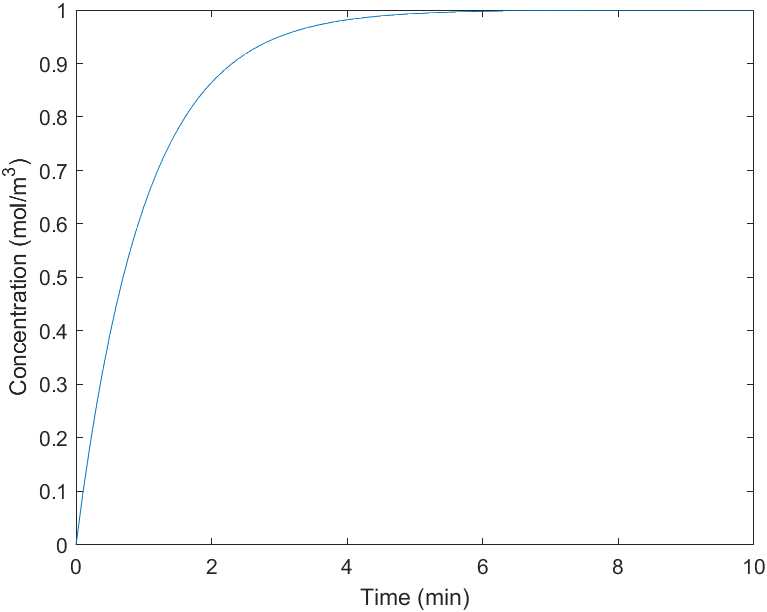

### Energy Balance

viewSolutionEnergy(false)

An energy balance for this application starts with the balance equation for enthalpy, $h$. Enthalpy is related to temperature as $m\ c_p(T-T_{ref})$where $c_p$ is the heat capacity. With a constant reference temperature ($T_{ref}$), this reduces to the following.


$$m c_{p} \frac{d T}{d t}=\sum \dot{m}_{i n} c_{p}\left(T_{i n}-T_{r e f}\right)-\sum \dot{m}_{o u t} c_{p}\left(T_{o u t}-T_{r e f}\right)+Q+W_{s}$$


There is no heat input $Q$, shaft work $W_s$, or reaction. Reduce this energy balance by eliminating any terms and simplifying the expression. Implement the additional energy balance equation and simulate a feed temperature change from 350 K to 300 K. The tank fluid is initially at 350 K. The liquid heat capacity is constant and does not depend on the concentration of $A$.

SIMULATE THE TEMPERATURE AND CONCENTRATION WITHIN THE TANK USING A FUNCTION AND` ode45 `. THEN, PLOT THE CONCENTRATION AND TEMPERATURE OVER TIME

ADD FUNCTIONS FOR SIMULATING SPECIES AND ENERGY BALANCE BELOW

### Solutions

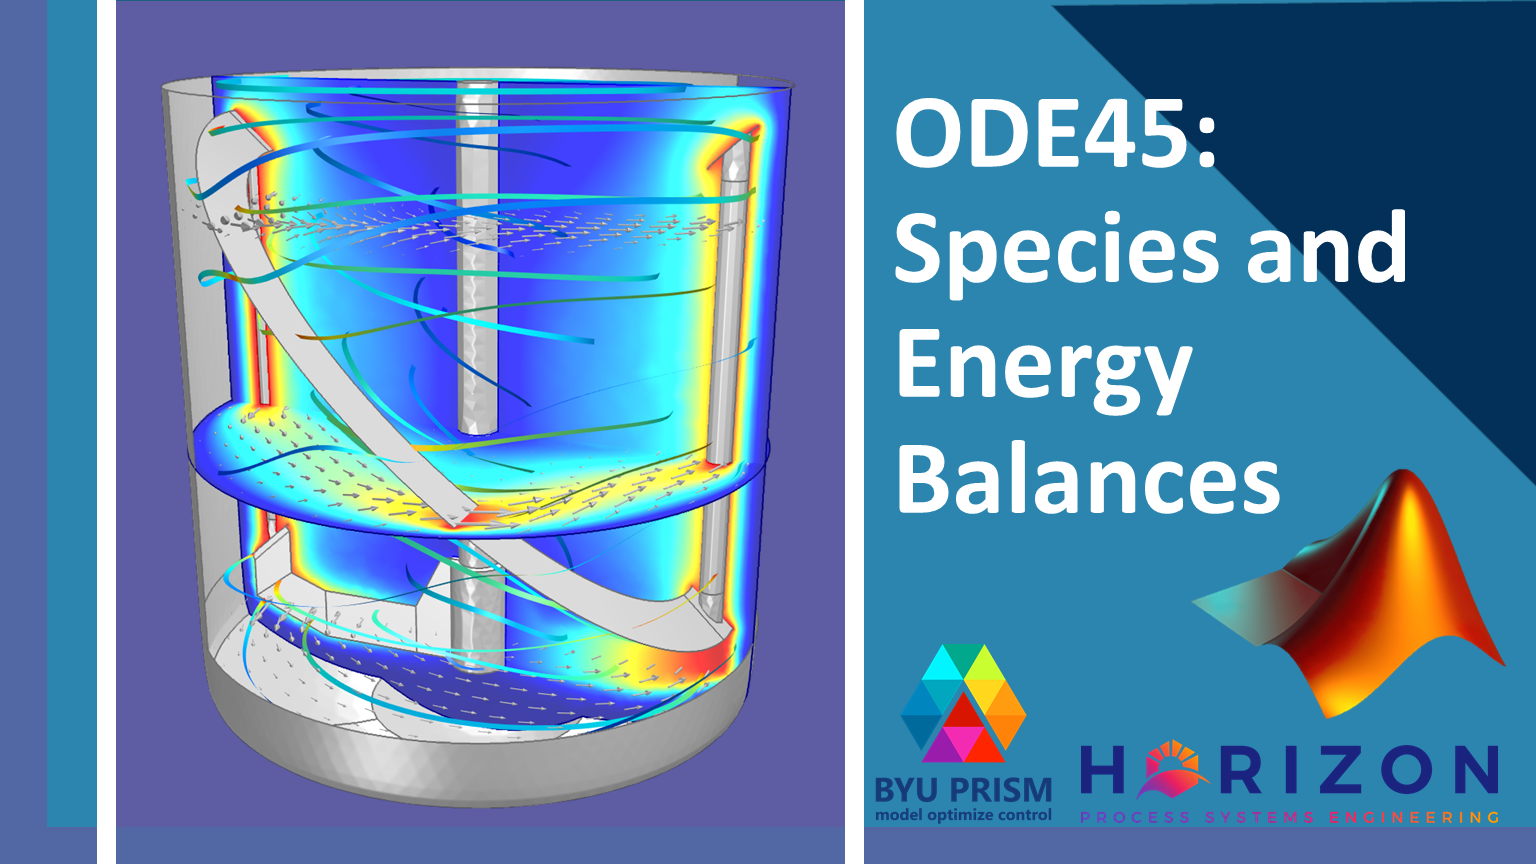

[View Solution Video](https://youtu.be/gUftbaDsMnA)

function viewSolutionSpecies(view)
if view
disp("% Simulate mixer" + newline + ...
     "[t, y] = ode45(@(t,y) materialBalance(t, y, q, V, Tf, Caf), time, Ca0);" + newline + ...
     "" + newline + ...
     "% Plot Results" + newline + ...
     "plot(t,y)" + newline + ...
     "xlabel('Time (min)')" + newline + ...
     "ylabel('Concentration (mol/m^3)')" + newline + ...
     "" + newline + ...
     "function dCadt = materialBalance(t, y, q, V, Tf, Caf)" + newline + ...
     "% INPUTS (2)" + newline + ...
     "% Tf: Feed Temperature (K)" + newline + ...
     "% Caf: Feed Concentration (mol/m^3)" + newline + ...
     "% STATES (2)" + newline + ...
     "% Ca: Concentration of A (mol/m^3)" + newline + ...
     "% t: time (min)" + newline + ...
     "Ca = y(1);" + newline + ...
     "dCadt = q/V * (Caf - Ca);" + newline + ...
	 "end")
end
end

function viewSolutionEnergy(view)
if view
	disp("% SIMULATE ENERGY BALANCE BELOW" + newline + ...
	     "%%%%%%%%%%%%%%%%%%%%" + newline + ...
	     "% Initial Conditions" + newline + ...
	     "Ca0 = 0.0;  % Ca" + newline + ...
	     "T0 = 350.0;  % K" + newline + ...
	     "i0 = [Ca0; T0];" + newline + ...
	     "% Feed Temperature (K)" + newline + ...
	     "Tf = 300;" + newline + ...
	     "% Feed concentration (mol/m^3)" + newline + ...
	     "Caf = 1;" + newline + ...
	     "% Time interval" + newline + ...
	     "time = linspace(0, 10, 101);" + newline + ...
	     "" + newline + ...
	     "% Simulate mixer" + newline + ...
	     "[t, y] = ode45(@(t,y) mixer(t, y, q, V, Tf, Caf), time, i0);" + newline + ...
	     "" + newline + ...
	     "% Plot Results" + newline + ...
	     "subplot(2,1,1)" + newline + ...
	     "plot(t,y(:,1))" + newline + ...
	     "ylabel('Concentration (mol/m^3)')" + newline + ...
	     "subplot(2,1,2)" + newline + ...
	     "plot(t,y(:,2))" + newline + ...
	     "xlabel('Time (min)')" + newline + ...
	     "ylabel('Temperature (K)')" + newline + ...
	     "" + newline + ...
	     "% ADD FUNCTION CODE BELOW" + newline + ...
	     "%%%%%%%%%%%%%%%%%%%%" + newline + ...
	     "% Material Balance" + newline + ...
	     "function dCadt = materialBalance(t, y, q, V, Tf, Caf)" + newline + ...
	     "% INPUTS (2)" + newline + ...
	     "% Tf: Feed Temperature (K)" + newline + ...
	     "% Caf: Feed Concentration (mol/m^3)" + newline + ...
	     "% STATES (2)" + newline + ...
	     "% Ca: Concentration of A (mol/m^3)" + newline + ...
	     "% t: time (min)" + newline + ...
	     "Ca = y(1);" + newline + ...
	     "dCadt = q/V * (Caf - Ca);" + newline + ...
	     "end" + newline + ...
	     "" + newline + ...
	     "% Material and Energy Balance" + newline + ...
	     "function output = mixer(t, y, q, V, Tf, Caf)" + newline + ...
	     "% INPUTS (2)" + newline + ...
	     "% Tf: Feed Temperature (K)" + newline + ...
	     "% Caf: Feed Concentration (mol/m^3)" + newline + ...
	     "% STATES (3)" + newline + ...
	     "% Ca: Concentration of A (mol/m^3)" + newline + ...
	     "% T: Temperature (K)" + newline + ...
	     "% t: time (min)" + newline + ...
	     "% unpack states" + newline + ...
	     "Ca = y(1);" + newline + ...
	     "T = y(2);" + newline + ...
	     "" + newline + ...
	     "dCadt = q/V * (Caf - Ca);" + newline + ...
	     "dTdt =  q/V * (Tf - T);" + newline + ...
	     "" + newline + ...
	     "% note that with multiple outputs, it must be in vector form" + newline + ...
	     "output = [dCadt; dTdt];" + newline + ...
	 "end")
end
end